# **Taller 11 modelo epidemiologico**

#### **INVACIÓN ZOMBIE**

Autor: Estefanía Citelly Guzmán

Fecha: 9/30/2023

## **Introducción**

El objetivo de este taller es resolver numéricamente, por el método numérico de Runge-Kutta implementado en la función [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de MATLAB, la ecuación de estado de un modelo epidemiológico [SIRV](https://en.wikipedia.org/wiki/Compartmental_models_in_epidemiology#The_SIRV_model) (SIR con vacunados) no lineal en un archivo Live Script de MATLAB y  examinar el resultado.

Para ello, resolveremos 5 puntos: En el primero se resolverá numéricamente la ecuación diferencial no lineal con condiciones iniciales establecidas por el profesor y graficaremos las soluciones. se analizará cuál es el efecto de la vacunación y el porcentaje mínimo de la población que debe estar vacunada para que el pico de infectados zombies se incremente sólo en un 50% con respecto al porcentaje inicial de 10%.

En el segundo se graficará la solución de I(t) y se observará que pasa cuando el porcentaje inicial de personas infectadas I (0) y por ende el de personas susceptibles S(0) aumentan.

Para el tercer punto se observará que pasa con la gráfica de I(t) cuando  la tasa de transmisión del virus zombie β aumenta. Además de ello analizaremos de qué forma este valor puede ser manipulado por el ser humano y con cual valor se evitaría una epidemia zombie.

En el punto cuatro se analizará que ocurre con I(t) cuando la tasa de recuperación γ  aumenta y examinaremos con cual valor se elimina la epidemia y de qué forma los humanos podemos manipular este valor.

Finalmente, en el último punto estudiaremos que ocurre con la grafica de I(t) cuando la tasa de vacunación δ aumenta, de qué forma el humano puede variar este número y con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10%, es decir, llegue a 0.2.

## Metodología

Utilizaremos una metodología analítica en donde a través de  un modelo epidemiológico SIRV no lineal, tomaremos los problemas de valores iniciales, hallaremos su solución  numéricamente, por el método de Runge-Kutta efectuando el comando [ode45](https://www.mathworks.com/help/matlab/ref/ode45.html) de matlab. Realizaremos las respectivas gráficas y posteriormente analizaremos su comportamiento.

**Modelo matemático:**

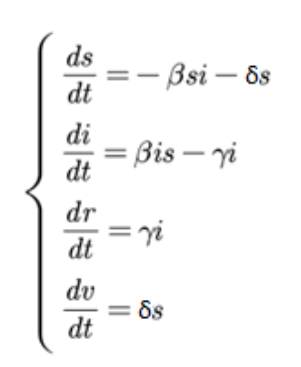

Supuestos: población cerrada (no llegan personas de otros lugares) y constante (*s* + *i* + *r* + *v* = 1), población uniforme, mezcla homogénea (sin consideraciones de edad, distribución espacial, educación o estructura social).

Donde, *s* es el porcentaje de personas susceptibles (pueden contraer la enfermedad), *i* es el porcentaje de personas infectadas, *r* es el porcentaje de personas recuperadas (y que no vuelven a contraer la enfermedad, es decir, quedan inmunes) y *v* es el porcentaje de personas vacunadas.

β es la tasa de transmisión, γ es la tasa de recuperación y aislamiento, y δ es la tasa de vacunación.

Observar que se tiene una epidemia creciente si (igual que en el caso SIR):

*R*0 es el número reproductivo básico.

Caso para estudiar (hay epidemia, *R*0 > 1): β = 0.1, γ = 0.02, δ = 0.001, *s*(0) = 0.8, *i*(0) = 0.1, *r*(0) = 0, *v*(0) = 0.1

## Resultados

## **punto 1  Soluciones numéricas Modelo Invasion Zombie**

Resolver numéricamente la ecuación diferencial no lineal y graficar las soluciones. ¿Cuál es el efecto de la vacunación? ¿Qué porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente sólo en un 50% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.15)?

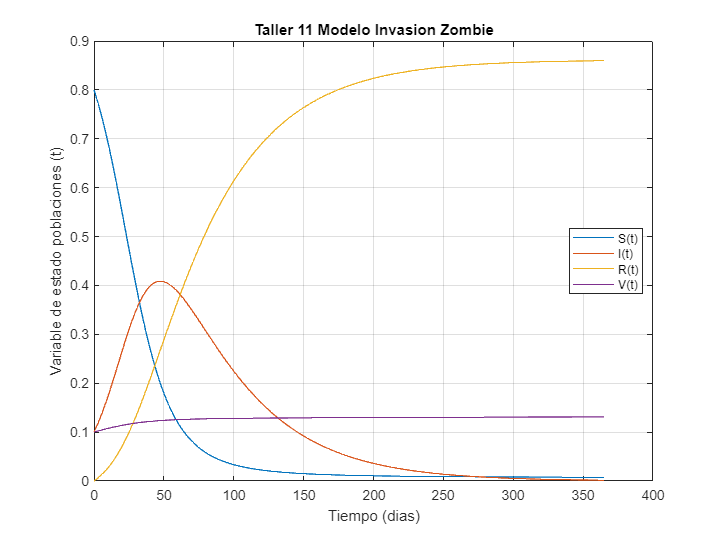

% Defino las variables de estado
syms S(t) I(t) R(t) V(t)

% Defino las constantes:
% Tasa de transmision
Beta = 0.1;
% Tasa de vacunacion
Gamma = 0.02;
% Tasa de recuperacion
Delta = 0.001;

% Creo las ecuaciones de estado para la invasion zombie
Tasa_SZombies = -Beta*S*I - Delta*S;
Tasa_IZombies = Beta*I*S - Gamma*I;
Tasa_RZombies = Gamma*I;
Tasa_VZombies = Delta*S;
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S I R V]);

% METODO NUMERICO
% Tiempo de muestreo para la invasion zombie: de 1 dia
h = 1;
% Vamos a trabajar 1 año
tmin = 0;
tmax = 365;
% Construir el vector de tiempo para la solucion
tspan = tmin:h:tmax;

% Defino condiciones iniciales: la suma total debe dar 1
Ci_S = 0.8;
Ci_I = 0.1;
Ci_R =  0;
Ci_V = 0.1;

% Como vamos a resolver numericamente armamos el vector de condiciones
Ci = [Ci_S Ci_I Ci_R Ci_V];

%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45
[t1,Sol1] = ode45(Funciones_estado,tspan,Ci);
I_sol1=Sol1(:,2);


% Punto 1 Simulamos:
% Graficar la solucion
figure
plot(t1,Sol1)
xlabel('Tiempo (dias)')
ylabel ('Variable de estado poblaciones (t)')
grid on
title('Taller 11 Modelo Invasion Zombie')
legend({'S(t)','I(t)','R(t)','V(t)'}, 'Location', 'best')

#### Cambiando V(0)

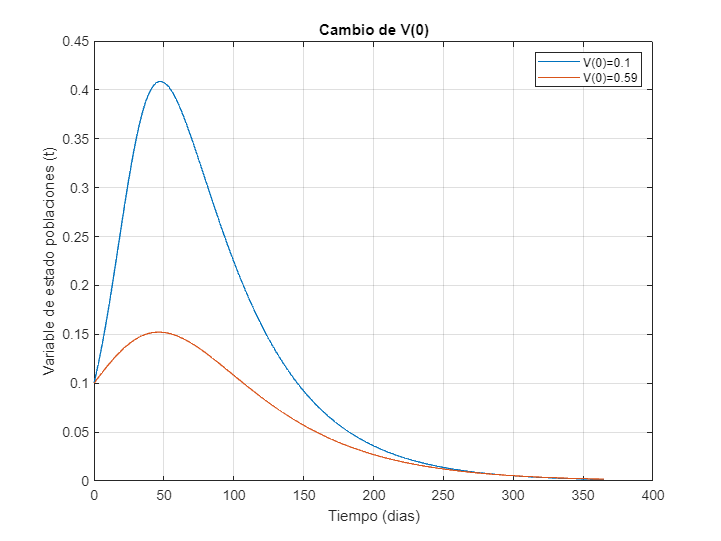

value=0.41;
Ci = [0.8-value 0.1 0 0.1+value]; 

[t1b,sol1b] = ode45 (Funciones_estado,tspan,Ci);
I_sol1b= sol1b (:,2);

plot(t1,I_sol1,t1b,I_sol1b)
title('Cambio de V(0)')
xlabel('Tiempo (dias)')
ylabel ('Variable de estado poblaciones (t)')
grid on
legend({'V(0)=0.1','V(0)=0.59'})

## **punto 2 Soluciones numéricas con un cambio de I(0)**

Graficar sólo la solución *i*(*t*) con un aumento sólo de *i*(0) y usando al menos 5 valores. Observar que al cambiar *i*(0) cambia *s*(0), dado que la suma de todas las condiciones iniciales debe ser igual a 1. Interpretar los resultados.

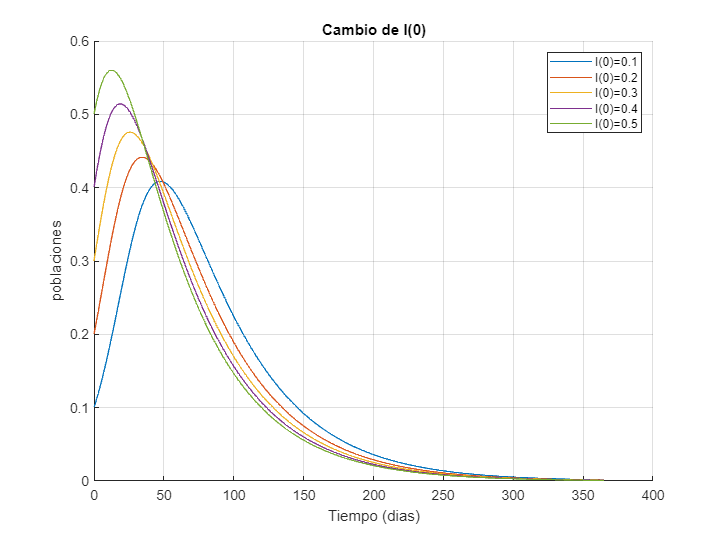

% Defino las variables de estado
syms S(t) I(t) R(t) V(t)

% Defino las constantes:
% Tasa de transmision
Beta = 0.1;
% Tasa de vacunacion
Gamma = 0.02;
% Tasa de recuperacion
Delta = 0.001;

% Creo las ecuaciones de estado para la invasion zombie
Tasa_SZombies = -Beta*S*I - Delta*S;
Tasa_IZombies = Beta*I*S - Gamma*I;
Tasa_RZombies = Gamma*I;
Tasa_VZombies = Delta*S;
% usamos el comando odeFunction para resolver
Funciones_estado = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S I R V]);

% METODO NUMERICO
% Tiempo de muestreo para la invasion zombie: de 1 dia
h = 1;
% Vamos a trabajar 1 año
tmin = 0;
tmax = 365;
% Construir el vector de tiempo para la solucion
tspan = tmin:h:tmax;

% Defino condiciones iniciales: cambiamos S, I, la suma total debe dar 1
multipleci = [0.8 0.1 0 0.1
      0.7 0.2 0 0.1
      0.6 0.3 0 0.1
      0.5 0.4 0 0.1
      0.4 0.5 0 0.1];
%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45 y graficamos
figure
for K = 1:length(multipleci)
[t,Sol2] = ode45(Funciones_estado,tspan,multipleci(K,:));
hold on
 plot(t,Sol2(:,2))
 title('Cambio de I(0)')
xlabel('Tiempo (dias)')
ylabel ('poblaciones')
grid on
legend({'I(0)=0.1','I(0)=0.2','I(0)=0.3','I(0)=0.4','I(0)=0.5' })
end

## **punto 3  Soluciones numéricas con un cambio de **β

Graficar sólo la solución *i*(*t*) con un aumento sólo de β y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor máximo de beta (diferente de cero) se evitaría una epidemia? Interpretar los resultados.

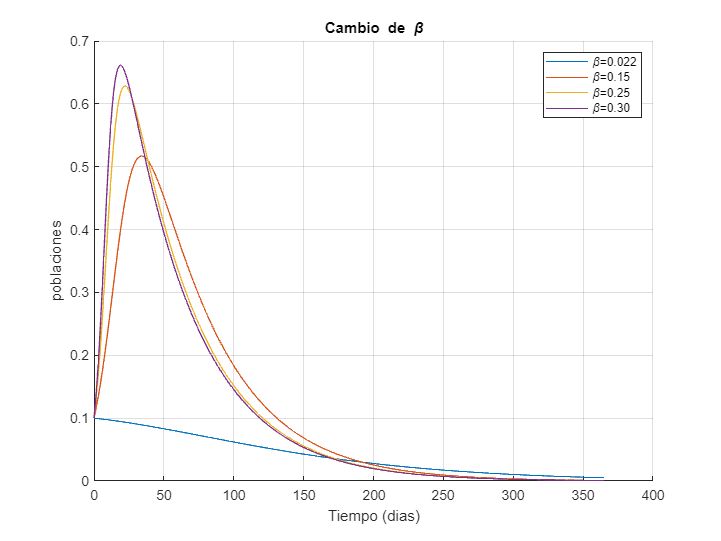

% Defino las variables de estado
syms S(t) I(t) R(t) V(t)

% Defino las constantes:
% Tasa de transmision,aumenta
Beta = [0.022 0.15 0.25 0.30];
% Tasa de vacunacion
Gamma = 0.02;
% Tasa de recuperacion
Delta = 0.001;

% Ecuaciones
Tasa_RZombies = Gamma*I;
Tasa_VZombies = Delta*S;


% METODO NUMERICO
% Tiempo de muestreo para la invasion zombie: de 1 dia
h = 1;
% Vamos a trabajar 1 año
tmin = 0;
tmax = 365;
% Construir el vector de tiempo para la solucion
tspan = tmin:h:tmax;

% Defino condiciones iniciales: la suma total debe dar 1
ci = [0.8 0.1 0 0.1];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45 y graficamos
figure
for K = 1:length(Beta)

%ecuaciones
Tasa_SZombies = -Beta(K)*S*I - Delta*S;
Tasa_IZombies = Beta(K)*S*I - Gamma*I;
% usamos el comando odeFunction para resolver
f = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S I R V]);

[t,Sol3] = ode45(f,tspan,ci);
hold on
 plot(t,Sol3(:,2))
 title('Cambio de \beta')
xlabel('Tiempo (dias)')
ylabel ('poblaciones')
grid on
legend({'\beta=0.022','\beta=0.15','\beta=0.25','\beta=0.30' })
end

## **punto 4 Soluciones numéricas con un cambio de **γ 

Graficar sólo la solución *i*(*t*) con un aumento sólo de γ y usando al menos 5 valores. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con cuál valor mínimo de γ se evitaría una epidemia? Interpretar los resultados.

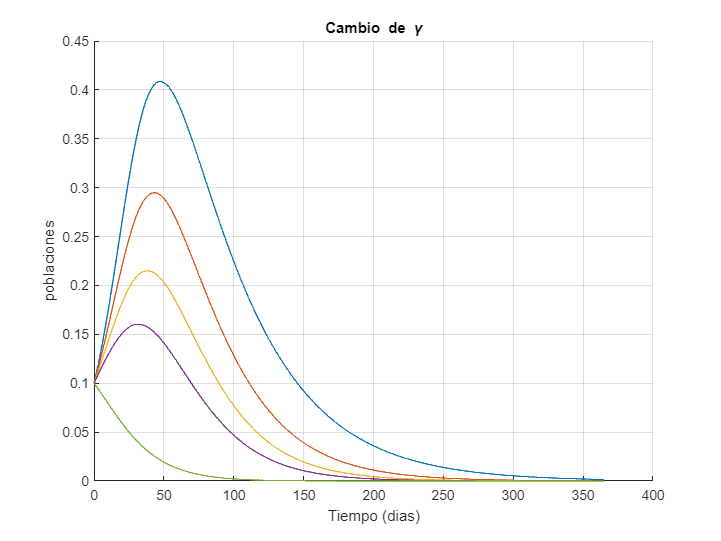

% Defino las variables de estado
syms S(t) I(t) R(t) V(t)

% Defino las constantes:
% Tasa de transmision
Beta = 0.1;
% Tasa de vacunacion, aumenta
Gamma = [0.02 0.03 0.04 0.05 0.099];
% Tasa de recuperacion
Delta = 0.001;

% Ecuaciones
Tasa_SZombies = -Beta*S*I - Delta*S;
Tasa_VZombies = Delta*S;


% METODO NUMERICO
% Tiempo de muestreo para la invasion zombie: de 1 dia
h = 1;
% Vamos a trabajar 1 año
tmin = 0;
tmax = 365;
% Construir el vector de tiempo para la solucion
tspan = tmin:h:tmax;

% Defino condiciones iniciales: la suma total debe dar 1
ci = [0.8 0.1 0 0.1];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45 y graficamos
figure
for K = 1:length(Gamma)

%ecuaciones

Tasa_IZombies = Beta*I*S - Gamma(K)*I;
Tasa_RZombies = Gamma(K)*I;

% usamos el comando odeFunction para resolver
f = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S I R V]);

[t,Sol4] = ode45(f,tspan,ci);
hold on
 plot(t,Sol4(:,2))
 title('Cambio de \gamma')
xlabel('Tiempo (dias)')
ylabel ('poblaciones')
grid on
legend({'\gamma=0.02','\gamma=0.03','\gamma=0.04','\gamma=0.05' ,'\gamma=0.099'})
end

## **punto 5 Soluciones numéricas con un cambio de** δ 

Graficar sólo la solución *i*(*t*) con un aumento sólo de δ y usando al menos 5 valores, uno de los cuales debe ser igual a cero. Este valor puede ser manipulado (¿cómo?) por el ser humano y de esta manera se puede considerar una entrada del sistema. ¿Con qué tasa mínima se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10% (es decir, llegue a 0.2)? Interpretar los resultados.

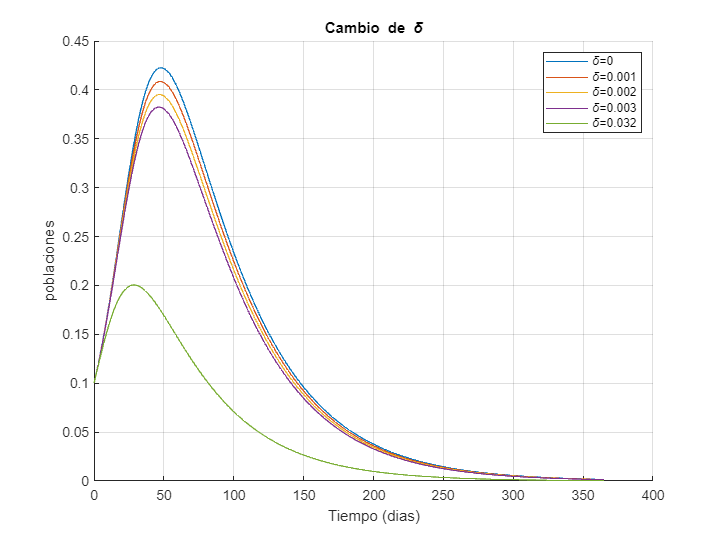


% Defino las variables de estado
syms S(t) I(t) R(t) V(t)

% Defino las constantes:
% Tasa de transmision
Beta = 0.1;
% Tasa de vacunacion
Gamma = 0.02;
% Tasa de recuperacion, aumenta
Delta = [0 0.001 0.002 0.003 0.032];

% Ecuaciones
Tasa_IZombies = Beta*I*S - Gamma*I;
Tasa_RZombies = Gamma*I;

% METODO NUMERICO
% Tiempo de muestreo para la invasion zombie: de 1 dia
h = 1;
% Vamos a trabajar 1 año
tmin = 0;
tmax = 365;
% Construir el vector de tiempo para la solucion
tspan = tmin:h:tmax;

% Defino condiciones iniciales: la suma total debe dar 1
ci = [0.8 0.1 0 0.1];


%SOLUCION METODO NUMERICO 
% Resolver usando el comando ODE45 y graficamos
figure
for K = 1:length(Delta)

%ecuaciones

Tasa_SZombies = -Beta*S*I - Delta(K)*S;
Tasa_VZombies = Delta(K)*S;

% usamos el comando odeFunction para resolver
f = odeFunction([Tasa_SZombies Tasa_IZombies Tasa_RZombies Tasa_VZombies],[S I R V]);

[t,Sol5] = ode45(f,tspan,ci);
hold on
 plot(t,Sol5(:,2))
 title('Cambio de \delta')
xlabel('Tiempo (dias)')
ylabel ('poblaciones')
grid on
legend({'\delta=0', '\delta=0.001','\delta=0.002','\delta=0.003' ,'\delta=0.032'})
end

## **Análisis y discusión de los resultados:**

### **punto 1 :**

#### **Efecto de la vacunación:**

A medida que más individuos se vacunan, la cantidad de personas **susceptibles (S)** al virus disminuye, lo que a su vez reduce las oportunidades propagación del virus, permitiendo que el número de zombies **infectados (I)** decrezca, pues entre más personas sean vacunadas, hay menos susceptibles con las que los infectados pueden entrar en contacto y transmitirles la enfermedad.

**Recuperados (R):** La vacunación no afecta directamente el número de recuperados. Sin embargo, al reducir la propagación del virus, también se reduce el número de nuevos infectados y, por lo tanto, el número de personas que se recuperarán.

La influencia de la vacunación es importante para controlar una invasión zombie ya que puede ayudar a alcanzar la inmunidad colectiva, lo que significa que incluso las personas no vacunadas están protegidas porque hay menos personas susceptibles en la población.

#### **Análisis del porcentaje mínimo de la población debe estar vacunada para que el pico de infectados se incremente  en un 50% con respecto al porcentaje inicial de 10% :**

Para abordar este problema, primero necesitamos comprender cómo la tasa de vacunación *v* afecta el pico de infectados:

 En el modelo SIRV, el pico de infectados ocurre cuando la tasa de cambio de infectados *i* alcanza su **valor máximo, **lo que significa que la tasa de cambio está pasando de positiva a negativa. Esto se produce cuando el número de personas susceptibles *s* disminuye lo suficiente y el número de infectados aumenta a su máximo.

El pico de infectados se da cuando:

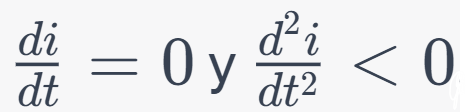

La ecuación que describe el cambio en el número de infectados es:

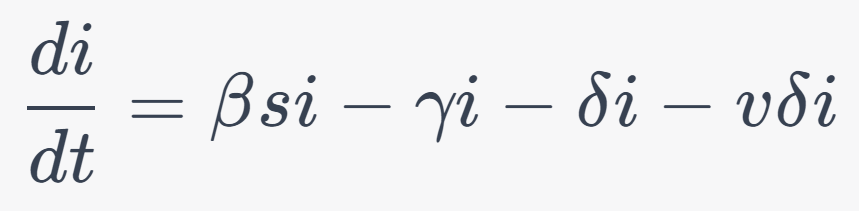

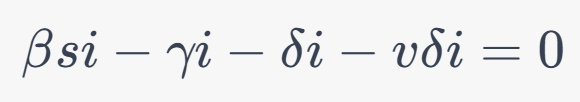

Valores conocidos:

- Inicialmente, el pico de infectados es del 10% (0.1).

- Queremos que el pico de infectados se incremente solo en un 50%, lo que significa que el nuevo pico es del 15% (0.15).

- Dado que se tienen los siguientes valores específicos para β=0.1, γ=0.02, δ= 0.001

Podemos sustituir los valores conocidos en la ecuación del pico de infectados:

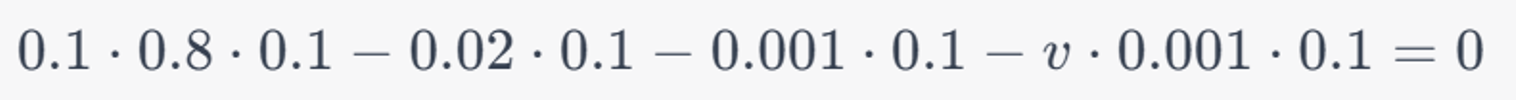

Simplificando:

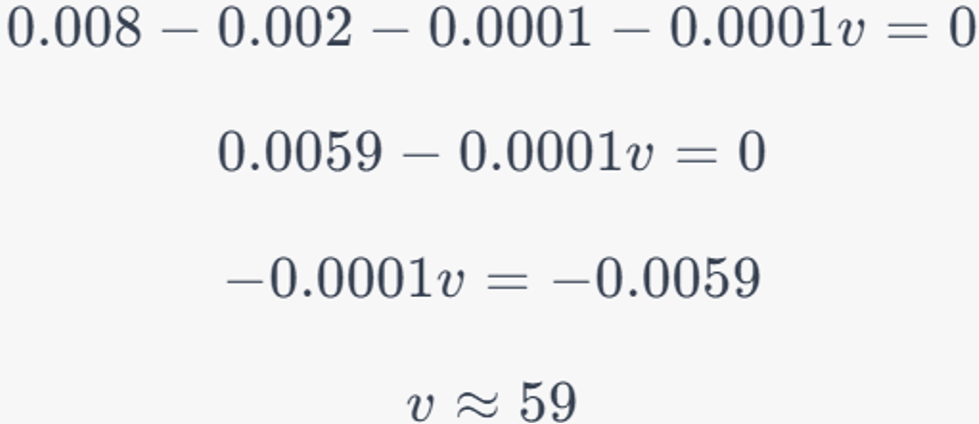

El valor aproximado de v que cumple con las condiciones dadas es v≈59. Esto significa que alrededor del 59% de la población debe estar vacunada para que el pico de infectados aumente solo un 50% con respecto al porcentaje inicial de 10%.

**punto 2 :**

Conforme aumentamos el valor inicial de i(0), el valor inicial de la tasa de cambio de infectados (di/dt) también aumenta. Lo cual indica que el número de nuevos casos en el inicio de la epidemia es más alto cuando comenzamos con un mayor número de individuos infectados.  Esto tendrá un impacto significativo en cómo se desarrolla una epidemia zombie, afectando la velocidad de propagación y la magnitud del pico de infección.

- **Mayor número de infectados inicialmente:**A medida que aumenta *i*(0), hay más individuos infectados al comienzo de la simulación. Esto puede llevar a una propagación más rápida de la enfermedad en las primeras etapas.

- **Posiblemente un pico de infección más alto:**Con un valor inicial más alto de *i*(0), es posible que se alcance un pico de infección más alto antes de que la enfermedad comience a disminuir. Esto depende de la dinámica específica del modelo.

- **Mayor necesidad de intervenciones:**Con un valor inicial más alto de  *i*(0), es más probable que se requieran intervenciones de control, como la vacunación, para reducir la propagación de la enfermedad y evitar que alcance niveles críticos.

- **Impacto en la inmunidad colectiva:** Un valor inicial más alto de *i*(0) puede influir en la cantidad de inmunidad colectiva necesaria para controlar la epidemia. Una mayor cantidad de personas necesitará estar inmunizada para alcanzar la inmunidad colectiva y frenar la propagación de la enfermedad.

**punto 3 :**

Cuando se aumenta el valor de β en un modelo epidemiológico SIRV, se está aumentando la tasa de transmisión. Esto significa que los individuos infectados tienen más probabilidades de transmitir la enfermedad a los individuos susceptibles. Generando así que la tasa de cambio de infectados (di/dt) también aumente significativamente. En otras palabras, un mayor valor de β conlleva una propagación más rápida de la enfermedad y posiblemente un mayor número total de casos a lo largo del tiempo.

Para evitar una epidemia, necesitamos que la tasa de infección β sea lo suficientemente baja para que el número reproductivo básico R0 sea menor que 1


$$\frac{\beta }{\gamma +\delta }<R_0 \;$$


Reemplazando los valores de *γ*=0.02 y *δ*=0.001 


$$\frac{\beta }{0\ldotp 02+0\ldotp 001}<1$$



$$\beta <0\ldotp 022$$


Por lo tanto, para evitar una epidemia en este modelo específico, el valor máximo de *β*  debería ser menor que 0.022. Esto significa que la tasa de infección no debe exceder 0.022 para mantener el número efectivo de reproducción por debajo de 1 y prevenir la propagación descontrolada de la enfermedad.

Para disminuir la tasa de transmisión en una epidemia zombie y llegar a los valores descritos anteriormente se podrían implementar algunos métodos:

- **Control de Población y Movimiento Restringido**: Implementar medidas de control de población y restringir el movimiento para evitar la propagación de la infección.

- **Comunicación y Coordinación**: Establecer sistemas de comunicación efectivos para mantener a las personas informadas sobre las condiciones y las estrategias de supervivencia.

- **Suministros y Almacenamiento de Alimentos**: Asegurarse de que las comunidades tengan suficientes suministros de alimentos no perecederos y agua para sobrevivir durante un período prolongado y evitar así que se expongan a los zombies para buscar alimentos.

- **Creación de Equipos de Rescate y Defensa**: Organizar equipos para rescatar a personas atrapadas y para proteger a las comunidades de los ataques de zombies.

- **Evacuación Segura y Refugios Fortificados**: Organizar evacuaciones hacia áreas seguras y establecer refugios fortificados donde las personas puedan protegerse de los zombies.

- **Barricadas y Trampas**: Crear barreras físicas y trampas para mantener a los zombies fuera de áreas seguras.

- **Desarrollo de Estrategias de Ataque**: Investigar y desarrollar técnicas de defensa para neutralizar zombies de manera segura.

**punto 4 :**

Conforme aumentamos el valor inicial de *γ*, el valor inicial de la tasa de cambio de infectados (di/dt) disminuye significativamente. Esto indica que la enfermedad se propaga más lentamente con valores más altos de *γ*. Por lo tanto, un mayor valor de *γ* conlleva una propagación más lenta de la enfermedad y posiblemente un menor número total de casos a lo largo del tiempo. La elección de *γ* es crucial en la gestión de una epidemia y puede influir en

Para evitar una epidemia, necesitamos que el número reproductivo básico R0 sea menor que 1


$$\frac{\beta }{\gamma +\delta }<R_0 \;$$


Reemplazando los valores de  *β* =0.1 y *δ*=0.001 


$$\frac{0\ldotp 1}{\gamma +0\ldotp 001}<1$$



$$0\ldotp 099<\gamma$$


Por lo tanto, para evitar una epidemia en este modelo específico, el valor máximo de  γ debería ser mayor que0.099. Esto significa que la tasa de recuperación debe ser mayor que 0.099 para mantener el número efectivo de reproducción (R0) por debajo de 1 y prevenir la propagación descontrolada de la enfermedad.

Estas tasas se podrian alcanzar esta tasa de recuperación se deben implementar estas medidas:

- **Equipo Médico y Suministros**: Abastecer los refugios con suministros médicos esenciales, incluyendo medicamentos, vendajes, antídotos y herramientas quirúrgicas.

- **Personal Médico y Voluntarios Capacitados**: Contar con profesionales de la salud y voluntarios entrenados para proporcionar atención médica, cirugías menores y primeros auxilios.

- **Aislamiento de los Infectados**: Separar a los individuos infectados para prevenir la propagación de la infección. Esto permitirá que los no infectados recuperen sin riesgo de contagio.

- **Cuarentenas Estrictas**: Establecer áreas de cuarentena para aquellos que muestran síntomas de infección pero aún no han desarrollado la condición completa de zombie.

- **Investigación de una Cura**: Asignar recursos para investigar una posible cura o tratamiento que pueda revertir la condición de los infectados.

**punto 5 :**

Conforme aumentamos el valor inicial de *δ*, el valor inicial de la tasa de cambio de infectados (di/dt) disminuye. Esto indica que la enfermedad se propaga más lentamente con tasas de vacunación más altas. Por lo tanto, una mayor tasa de vacunación conlleva una propagación más lenta de la enfermedad y por ende un menor número total de casos a lo largo del tiempo. La vacunación es una herramienta clave en la gestión de una epidemia y puede tener un impacto significativo en su curso. La tasa mínima con la que se debe vacunar la población de manera que el pico de infectados se incremente sólo en un 100% con respecto al porcentaje inicial de 10%, es decir, llegue a 0.2. es de 0.032. En una situación de epidemia de zombies, donde representan una amenaza similar a una enfermedad contagiosa, se podría alcanzar esta tasa de vacunación si se toman algunas estrategias para proteger a la población:

- **Educación y concientización de la sociedad**: Difundir información precisa y clara sobre cómo prevenir la infección zombie es crucial. Esto puede incluir campañas de concienciación, anuncios, folletos y programas educativos.

- **Acceso Universal**: Garantizar que la vacuna esté disponible para toda la población, independientemente de su situación socioeconómica o geográfica. Esto podría requerir medidas para distribuir la "vacuna" de manera equitativa.

- **Implementación de Zonas Seguras**: Establecer áreas seguras donde las personas puedan recibir la vacuna de manera segura y controlada.

- **Comunicación Efectiva:** Mantener líneas de comunicación claras y efectivas entre los refugios y los equipos de rescate o suministro.